**Constants **

do= 0.05;  %%outer diameter of the seat post 
di=0.04 ; %% inner diameter of the seat post
E=71.7*10^9; %% modulus of elasticity of aluminium 
l=0.35; %%length of the seat post 
c=0.035/2; %% centroid of the seat post
I=(pi/64)*(do^4-di^4); %% moment of inertia 
Sy= 169*10^9; %yield stress of aluminium
Sut=341*10^6; %ultimate tensile strenght of steel 
f= 0.9;


**Loading scenario 1: Buckling on seat post **

- **Calculating critical pressure for buckling**

Pcr=((pi^2)*E*I)/(l^2)%% Critical pressure

Pcr = 1.0464e+06

**2.     Calculating the mass that would cause buckling**

A=0.5*0.143*0.27;%% Area of the seat
Fcr=Pcr*A; %%critical force
mcr=Fcr/9.81 %% buckling mass 

mcr = 2.0591e+03

**Loading scenario 2: Bending on seat post **

- **Calculating Moment generated by the bike rack on the seat post **

d=0.3; %distance from the post to the point load 
m=50: 10: 250; %%mass carried by the bike rack
F=9.8*m;
M=F*d;% moment generated by the point load

2. **Calculating the stress generated by the moment applied at the post **

sigma= M*c/I; 

3. **Factor of safety according to Distortion Energy Theory**

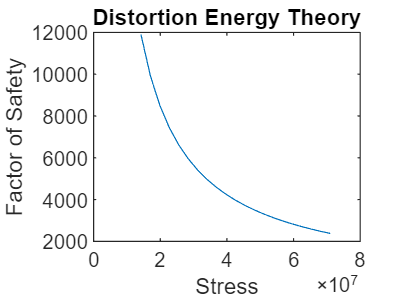

n_DE=Sy./sigma;
plot (sigma,n_DE)
title("Distortion Energy Theory")
ylabel ("Factor of Safety")
xlabel ("Stress")

disp(min(n_DE))

   2.3799e+09



disp(max(n_DE))

   1.1899e+10



3. **Factor of safety according to MSS Theory**

Tmax=sigma/2;
n_mss=(Sy/2)./Tmax

n_mss = 	1.0e+04 *

    1.1899    0.9916    0.8500    0.7437    0.6611    0.5950    0.5409    0.4958    0.4577    0.4250    0.3966    0.3719    0.3500    0.3305    0.3131    0.2975    0.2833    0.2704    0.2587    0.2479    0.2380


plot (sigma,n_mss)
hold on 
title("Maximum Shear Stress Theory")
ylabel ("Factor of Safety")
xlabel ("Stress")
disp (min(n_mss))

   2.3799e+03



disp (max(n_mss))

   1.1899e+04



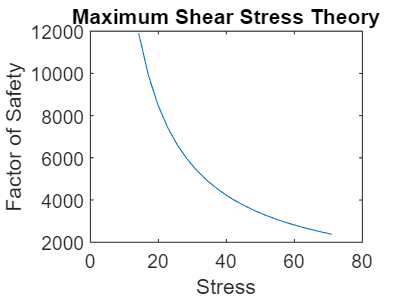

if sigma >= Sy 
disp 'oh no'
end
hold off

## **Fatigue Scenario **

- Calculating Se'

Se_prime=0.5*Sut %works only on Sut<1400 MPa

Se_prime = 170500000

- Calulating Marin factors 

Surface Factor: k_a 

a0= 4.51;
b0= -0.265;
k_a=a0*(341)^(b0); % a and b works only on machined surfaces 

Size modification factor: k_b

k_b=0.858; %non axial loading

Load Modification factor: k_c

k_c=1;% for bending 

Temperature modification Factor: k_d

for t = 50:10:100
k_d=0.975 + t*0.432*10^-3-t^2*0.115*10^-5+0.104*10^-8*t^3; 
Se=k_a*k_b*k_c*k_d*Se_prime;
a=(f*Sut)^2/Se;
b=-(1/3)*log10((f*Sut)/Se); 
N= 50*42*10^3;
Sf=a*N^b
end

Sf = 1.2849e+08

Sf = 1.2894e+08

Sf = 1.2936e+08

Sf = 1.2976e+08

Sf = 1.3013e+08

Sf = 1.3048e+08